# Code to generate the pattern for the cuts in the actuator sheet of the duct

developable sliding duct linkages

clear; close; clc;

## Initialization and Decalaration

missile_diameter = convlength(3.5, "in", "m"); % diameter of missile body (m)
area_duct = pi * convlength(1.5/2, "in", "m")^2; % area of each duct (m)

linkage_width = 1.8e-2; % width of each actuator linkage (m) - USE UNIT WIDTH FOR DEBUGGING
hinge_width = 1e-2; % hidth of hinge (m) -if elastic hinge then it is the vertical width of the material to be preserved

tolerance = 2e-4; % clearance between sliding components (m)

n_points_plot = 100; % number of points per line to plot n

## Preliminary Geomatric Computations

missile_circumfrence = pi * missile_diameter; % circumfrence of missile body (m)
quater_arc = missile_circumfrence / 4; % arc of pi radians on the missile

linkage_arc = sliding_duct_linkage_angle(missile_diameter/2, area_duct); % arc of missile body swept by the linkage
linkage_length = linkage_arc / (2*pi) * missile_circumfrence; % arc length of the linkages


% find the edges of the linkages and the mirror line for the unit cell of
% the duct
linkage_seperators = [0:3] * linkage_width;
mirror_line = 3.5 * linkage_width;
unit_cell_boundry_x = 7 * linkage_width

unit_cell_boundry_x = 0.1260


% quater acr points represent y coordiantes of the lower edge, the first
% continuous hingline and translate-duplicate boundary.
quater_arc_points = [-1, 0, 1] * quater_arc; % vertical location of quater arcs (m) 
hinge_line_points = [-.5, .5] * hinge_width; % verical location of hinge line (m)
linkage_ends = [-1,1] * linkage_length; % vertical location of linkage ends (m)


% create hermite splines for the linkages

% cut 1

% endpoints
P_0 = [linkage_seperators(2); linkage_ends(1)];
P_1 = [(linkage_seperators(2) + linkage_seperators(3)) / 2; hinge_line_points(2)];
P_2 = [linkage_seperators(3); quater_arc_points(3)];

% tangencis
T_0 = [0; 1]/20;
T_1 = [1; 0]/40; % horixontal at hinge
T_1 = [1; 1]/40; % smoother hinges but not horizontal at hinge
T_1 = (P_0-P_2)/40; % very smooth - probably the best option

% create the two sub component splines of cut 1
spline_1 = Hermite_spline(P_0, P_1, T_0, T_1, n_points_plot);
spline_2 = Hermite_spline(P_1, P_2, T_1, T_0, n_points_plot);

% assemble cut_1 from subcomponent splines
cut_1 = horzcat(spline_1,spline_2);

% cut 2
% flip and mirror vertically then translate horizontally
cut_2 = [cut_1(1, end:-1:1); -cut_1(2, :)] + [linkage_width; 0];

% apply tolerances to get the needed cuts with offsets
seperator = [NaN; NaN]; % include a nan seperator to ensure the ploting doesnt joint the splines
cuts = horzcat(cut_1, seperator, cut_2);

tolerance_shifter = [tolerance/2; 0];
cuts_left = cuts - tolerance_shifter;
cuts_right = cuts + tolerance_shifter;

% add a circular cap to the cut
theta = linspace(pi, 2*pi); % angle to sweep through for cut caps
cut_cap_1 = P_0 + tolerance/2 * [cos(theta); sin(theta)]; % semiciruclar cap
% place on top of cut two with the same tranformation applied to produce
% cut two and a flipping of the y component to orient it correctly
cut_cap_2 = [cut_cap_1(1, end:-1:1); -cut_cap_1(2, :)] + 2*[linkage_width; 0];

cut_caps = horzcat(cut_cap_1, seperator, cut_cap_2);

% now keep track of the cuts we actual want to do
% we want the left and right cuts as well as the caps that connect them
cuts = horzcat(cuts_left, seperator, cuts_right, seperator, cut_caps);


## Mirror and ducpliate cuts into unit cell

cuts_vertically_translated = cuts + 2*quater_arc * [0;1]; % shift vertically
cuts_unit_cell = horzcat(cuts, seperator, cuts_vertically_translated); % combine the cuts
cuts_unit_mirror = cuts_unit_cell .* [-1;1] + 2*mirror_line .* [1;0]; % mirror horizontally
cuts_unit_cell =  horzcat(cuts_unit_cell, seperator, cuts_unit_mirror); % combine the cuts

## plot cuts

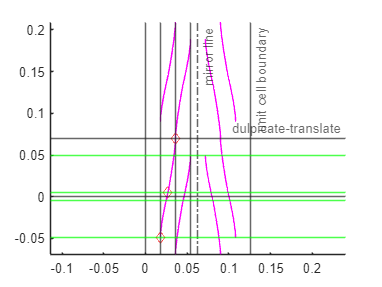



% for debugging purposes lets just plot the easy version of the gemotry
figure;
axis equal
hold on
%xlim([0,inf])

xline(linkage_seperators)
xline(mirror_line,"-.", "mirror line")
xline(unit_cell_boundry_x, "-", "unit cell boundary")

yline(quater_arc_points(1:2))
yline(quater_arc_points(3), "-","dulpicate-translate")
yline(hinge_line_points,"g-")
yline(linkage_ends,"g-")


plot(P_0(1), P_0(2),"r-diamond") % plot the first point of the cut
plot(P_1(1), P_1(2),"r-diamond") % plot the second point of the cut
plot(P_2(1), P_2(2),"r-diamond") % plot the third point of the cut

% plot(spline_1(1, :), spline_1(2, :), 'LineWidth', 2)
% plot(spline_2(1, :), spline_2(2, :), 'LineWidth', 2)

plot(cut_1(1, :), cut_1(2, :), "y-", 'LineWidth', 1)
plot(cut_2(1, :), cut_2(2, :), "y-", 'LineWidth', 1)


plot(cuts_left(1, :), cuts_left(2, :), "k-", 'LineWidth', 1)
plot(cuts_right(1, :), cuts_right(2, :), "k-", 'LineWidth', 1)
plot(cut_caps(1, :), cut_caps(2, :), "c-", 'LineWidth', 1)

plot(cuts(1, :), cuts(2, :), "c-", 'LineWidth', 1)

plot(cuts_unit_cell(1, :), cuts_unit_cell(2, :), "m-", 'LineWidth', 1)

## prepare for printing

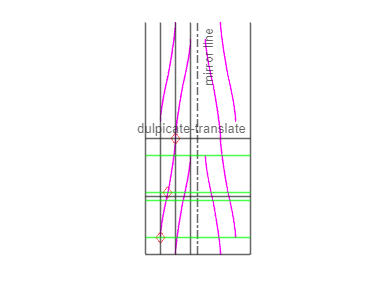

xlim([0,unit_cell_boundry_x])
axis off
% Set the remaining axes properties
set(gca,'DataAspectRatio',[1 1 1],'PlotBoxAspectRatio',...
    [1 2.21656818711568 15.8730158730159]);


% print settings
% left .35
% top -.99
% width 8.0
% Height 13.45

% the plan is this:
% create the L3 to L2 L1 L0 geometery
% mirror the geometery
% pattern the geometry as many times as needed